# Laboratório de Instrumentação Eletrônica Aplicada

##                 João vitor Viana do amaral, 304b.

                                            11 de junho de 2022.    

_______________________________________________________TP02

Objetivos

1. Verificar experimentalmente a lei de Ohm usando curvas características de resistor;

2. Analisar circuitos usando leis de Kirchhoff da voltagem (KVL) e corrente elétrica (KCL);

3. Verificar experimentalmente as leis de Kirchhoff;

4. Compreender aspectos de circuitos eletrônicos como polaridade, pinagem de componentes e indicação de nó de referência ou terra;

5. Simular circuitos eletrônicos básicos utilizando o Multisim;

6. Traçar experimentalmente curvas características de dipolos elétricos e circuitos série envolvendo componentes lineares (resistores) e não-lineares (LED e transistores);

## Lista de material

• Notebook

        NIELVIS Instruments: DMM, 2-wire, 3-wire.

        Matlab

• Módulo NIELVIS II+1 (um) cabo USB

• Caixa com alicate de corte, alicate de bico e cabos jumper de protoboard.

• 1 (um) par de cabos (vermelho+preto) para medições com o instrumento virtual DMM.

• Componentes discretos

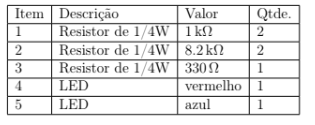

## Recomendações

• A recomendação é que se faça uma foto de você realizando os experimentos ilustrando sua presença no laboratório. Peça a um colega do seu grupo ou bancada que faça uma foto adequada.

                    foto minha no laboratorio.

• As formas de onda medidas com os instrumentos do NIELVIS II+ podem ser salvas em arquivos texto. Usando um programa Matlab adequado para cada instrumento virtual desenha-se os gráficos para serem inseridos no corpo do relatório.

• No final da prática, certifique-se de:

1. guardar as pontas de prova nas bolsas plásticas,

2. recolher e guardar componentes e ferramentas na caixa de sua bancada,

3. desligar os equipamentos de bancada (osciloscópio, NIELVIS),

4. encerrar sua seção no notebook e fechar a tampa do notebook.

5. guardar os cabos de energia e cabos USB, nos armários ou no suporte de cabos.

## 1 Parte teórica

## 1.1 Analisando o comportamento de circuito de um LED em série com um resistor.

    Um LED é um componente dipolo semicondutor não linear conforme ilustrado pelas curvas características na Figura 1. O modelo de um LED é aproximado por uma função linear por partes. Basicamente, observamos dois comportamentos bem distintos conforme ilustrado na Figura 2:

• Resistência elevada Raberto > 10MΩ para VLED red < 1.5V , i.e. uma chave aberta.

• Resistência pequena Rfechado < 30 Ω para VLED red < 1.5V , i.e. uma chave fechada em série com um resistor de 30 Ω.

Conectando um resistor em série com o LED, a característica na região de condução ou chave fechada é "dominada"pela resistência do resistor em série com o LED conforme mostrado na Figura 3. O resistor externo ao LED em série é essencial para limitar a corrente que circula através do LED. Note que LEDs de uso comum tem uma limitação de potência de 100mW e uma corrente máxima de 50mA. LEDs de potência para uso em iluminação são em geral

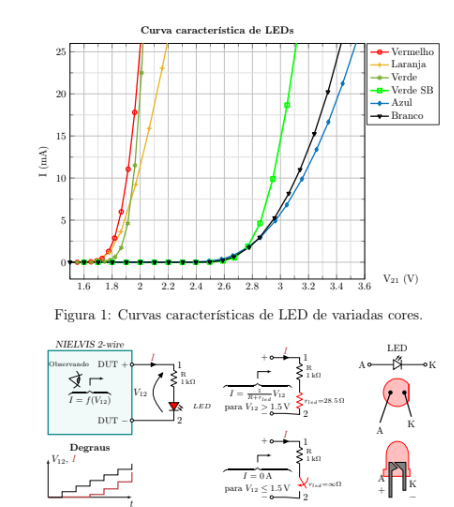

Figura 2: Arranjo experimental para determinação dos parâmetros do modelo estático de um LED em série com um resistor. de 3W ou maior. 

#### ATENÇÃO: a voltagem reversa de LEDs é em torno de 5V, um valor baixo se comparada com diodos, Vmax reverso = 60V

## 2 Parte experimental

## 2.1 Procedimentos

##     Parte experimental

1. Obtenha curvas características estáticas V×I para componentes e arranjos de circuito série e paralelo utilizando o instrumento virtual 2-Wire. Ajuste a faixa de voltagem para Vmax = 5 V e incremento de ∆V = 0.1 V.  Dica: Salve os dados em arquivo texto e utilize o Matlab para traçar as curvas superpostas em gráfico com os eixos identificados e as curvas com espessura de linha igual a 2 :

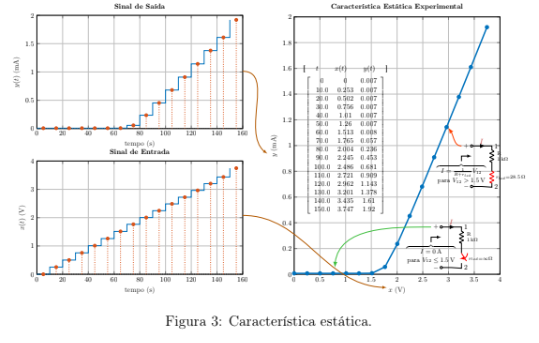

#### (a) Resistor:  experimente dois valores diferentes de resistência (e.g. 330Ω, 1kΩ) e

#### verifique se a inclinação obtida confere com os valores dos resistores.

i. Resistor: 330 Ω.

ii. Resistor: 1 kΩ.

____________________________________________________________________________

Resposta: Responder aqui inserindo esboço das curvas observadas.

%resistor de 330ohms
clear;clc;close all;
z=[0.003	0.021
0.101	0.316
0.197	0.609
0.299	0.916
0.399	1.219
0.490	1.495
0.592	1.802
0.689	2.095
0.790	2.401
0.896	2.722
0.983	2.986
1.081	3.280
1.182	3.586
1.279	3.879
1.381	4.191
1.472	4.466
1.573	4.772
1.668	5.058
1.768	5.359
1.868	5.660
1.964	5.952
2.060	6.243
2.161	6.549
2.263	6.857
2.359	7.147
2.461	7.457
2.552	7.734
2.653	8.037
2.749	8.328
2.848	8.630
2.951	8.939
3.047	9.231
3.143	9.522
3.244	9.827
3.339	10.115
3.441	10.422
3.536	10.711
3.632	11.000
3.732	11.301
3.828	11.591
3.928	11.895
4.029	12.200
4.125	12.491
4.220	12.777
4.321	13.082
4.423	13.393
4.522	13.691
4.620	13.987
4.708	14.254
4.816	14.580
4.914	14.877];
v=z(:,1);
i=z(:,2);
figure(1)
subplot(2,1,1)
plot(v,i)
title('resitor de 330 ohms')
xlabel('V_{12} (V)')
ylabel('i(mA)')

%resistor de 1k
z=[0.003	0.015
0.098	0.112
0.199	0.216
0.294	0.313
0.399	0.420
0.499	0.523
0.599	0.626
0.700	0.728
0.800	0.831
0.894	0.928
0.994	1.030
1.095	1.134
1.196	1.238
1.297	1.340
1.403	1.449
1.498	1.548
1.599	1.651
1.698	1.752
1.797	1.854
1.895	1.955
1.994	2.055
2.093	2.157
2.194	2.261
2.293	2.362
2.399	2.471
2.499	2.574
2.594	2.671
2.695	2.776
2.795	2.878
2.894	2.979
2.993	3.082
3.092	3.183
3.193	3.286
3.292	3.388
3.393	3.492
3.493	3.594
3.592	3.696
3.686	3.793
3.792	3.901
3.891	4.003
3.991	4.106
4.089	4.206
4.188	4.308
4.288	4.411
4.387	4.514
4.487	4.615
4.592	4.723
4.691	4.826
4.789	4.925
4.885	5.025
4.983	5.126];
v=z(:,1);
i=z(:,2);
subplot(2,1,2)
plot(v,i)
title('resitor de 1k ohms')
xlabel('V_{12} (V)')
ylabel('i(mA)')

____________________________________________________________________________

#### (b) LED: obtenha a curva característica para dois LEDs de cores diferentes mas

#### de uma mesma tecnologia. Obtenha valores para a resistência dinâmica (LED

#### conduzindo) dos LEDs. Lembrando que energia E é dada por E = h f, em que

#### f é frequência e h a constante de Planck. Verifique experimentalmente qual cor

#### de LED apresenta maior queda de voltagem sobre seus terminais e compare com

#### o resultado teórico esperado. Lembre-se que $\Delta{voltagem}=\frac{energia}{Carga-elétrica}$

____________________________________________________________________________

Resposta: Responder aqui inserindo esboço das curvas observadas.

%%led azul
clear;clc;close all;
z=[0.003	0.010
0.104	0.010
0.204	0.011
0.298	0.011
0.396	0.011
0.495	0.011
0.595	0.011
0.695	0.011
0.795	0.011
0.900	0.011
0.999	0.011
1.100	0.011
1.200	0.011
1.300	0.011
1.399	0.010
1.505	0.011
1.606	0.011
1.706	0.011
1.805	0.011
1.903	0.011
2.006	0.011
2.104	0.011
2.203	0.011
2.303	0.011
2.402	0.019
2.496	0.118
2.574	0.649
2.665	2.211
2.757	4.754
2.853	8.204
2.948	12.405
3.045	17.473
3.139	23.343
3.246	31.247
3.340	39.422];
v=z(:,1);
i=z(:,2);
a=v\i;
figure(2);
subplot(2,1,1)
plot(v,i)
xlabel('V_{12} (V)')
ylabel('i(mA)')
title('led azul')

%led vermelho
z=[0.003	0.011
0.104	0.011
0.204	0.011
0.298	0.011
0.397	0.011
0.495	0.011
0.595	0.011
0.695	0.011
0.795	0.010
0.900	0.012
1.000	0.010
1.100	0.011
1.201	0.011
1.301	0.011
1.400	0.011
1.505	0.011
1.606	0.019
1.703	0.073
1.783	0.437
1.877	2.540
1.961	6.003
2.064	11.186
2.161	16.401
2.262	22.040
2.352	27.140
2.456	33.046
2.551	38.335];
v=z(:,1);
i=z(:,2);
a=v\i;
subplot(2,1,2)
plot(v,i)
xlabel('V_{12} (V)')
ylabel('i(mA)')
title('led vermelho')

____________________________________________________________________________

(c) Combinação série de um LED e um resistor. Obtenha uma curva para cada valor

de resistor a seguir:

i. Resistor: 330 Ω.

ii. Resistor: 1 kΩ.

____________________________________________________________________________

Resposta: Responder aqui inserindo esboço das curvas observadas para os dois resistores

%led azul em serie com 330 ohms
clc;clear;close all;
z=[0.003	0.011
0.104	0.010
0.204	0.011
0.298	0.011
0.397	0.011
0.495	0.011
0.595	0.011
0.695	0.011
0.795	0.011
0.900	0.011
1.000	0.011
1.100	0.011
1.200	0.011
1.300	0.011
1.400	0.011
1.505	0.011
1.606	0.011
1.706	0.010
1.805	0.011
1.903	0.011
2.006	0.010
2.104	0.011
2.203	0.011
2.303	0.011
2.402	0.017
2.498	0.071
2.596	0.225
2.686	0.413
2.776	0.623
2.864	0.835
2.952	1.057
3.044	1.293
3.192	1.681
3.291	1.943
3.389	2.205
3.486	2.467
3.589	2.747
3.681	2.995
3.783	3.274
3.880	3.541
3.982	3.820
4.079	4.087
4.175	4.353
4.271	4.620
4.373	4.903
4.470	5.172
4.572	5.456
4.668	5.726
4.768	6.003
4.867	6.282
4.966	6.560];
v=z(:,1);
i=z(:,2);
a=v\i;
figure(3)
subplot(2,1,1)
plot(v,i)
xlabel('V_{12} (V)')
ylabel('i(mA)')
title('led azul em serie com resistor 330(\Omega)')
%led azul em serie com 1k ohms
z=[0.004	0.013
0.098	0.013
0.199	0.013
0.299	0.013
0.399	0.013
0.501	0.013
0.601	0.013
0.701	0.013
0.801	0.013
0.908	0.014
1.009	0.013
1.111	0.014
1.212	0.013
1.312	0.013
1.411	0.013
1.511	0.013
1.611	0.014
1.712	0.013
1.814	0.013
1.914	0.013
2.015	0.013
2.114	0.014
2.214	0.014
2.313	0.014
2.413	0.021
2.517	0.062
2.614	0.130
2.710	0.211
2.805	0.292
2.900	0.378
2.996	0.466
3.091	0.555
3.186	0.644
3.280	0.733
3.375	0.824
3.470	0.913
3.564	1.004
3.659	1.096
3.754	1.187
3.850	1.279
3.945	1.370
4.046	1.469
4.140	1.561
4.234	1.653
4.329	1.744
4.424	1.838
4.517	1.928
4.612	2.021
4.707	2.114
4.896	2.299
4.991	2.392];
v=z(:,1);
i=z(:,2);
a=v\i;
subplot(2,1,2)
plot(v,i)
xlabel('V_{12} (V)')
ylabel('i(mA)')
title('led azul em serie com resitor de 1k\Omega')

____________________________________________________________________________

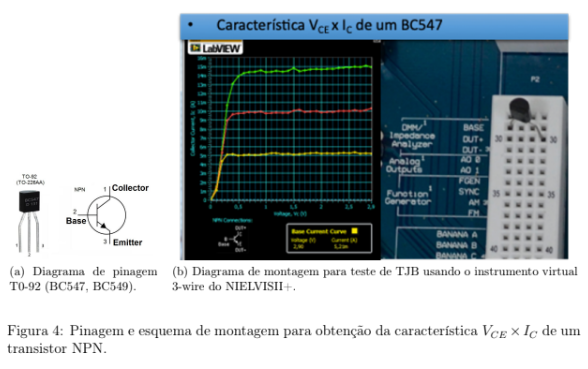

#### 2. Obtenha a característica estática VCE × IC para um transistor bipolar npn - BJT (e.g.

#### BC549 ou BC547, vide Figura 4) utilizando o instrumento virtual 3-Wire (obter 8

#### curvas).

%curva vce x ic
clear;clc;close all;

z1=[0.00511153	0.00002961
0.09920416	0.00332981
0.19684683	0.00393022
0.29473657	0.00398237
0.39639027	0.00398031
0.49756557	0.00405328
0.59497242	0.00401041

0.69883828	0.00403426
0.79450941	0.00409970
0.88273705	0.00403964
0.99415853	0.00402879
1.09761046	0.00408601
1.17948637	0.00402019
1.28859230	0.00410049
1.38521284	0.00404293
1.49079742	0.00407516
1.59475582	0.00415157

olhe os tres valores estimados para beta: 270.862667 , 258.706667 e 264.340000

1.69633005	0.00409106
1.79541990	0.00408163
1.89825730	0.00419173
1.99684206	0.00420491
2.09544844	0.00413353
2.19496394	0.00414824
2.25442732	0.00413615
2.35964614	0.00418559
2.45777519	0.00415963
2.55884547	0.00422614

olhe os tres valores estimados para r0 dinamico: 934.188240 , 1265.616417 e 580.919710

2.69500468	0.00419739
2.76519176	0.00424871
2.86213383	0.00414687
2.96564227	0.00419209
3.06020825	0.00421950
3.16299709	0.00424082
3.26191698	0.00426326
3.36228819	0.00423920
3.46357595	0.00425434
3.56275273	0.00426968
3.66240633	0.00421917
3.76404280	0.00435183
3.86951000	0.00424018
3.97113724	0.00427886
4.06033379	0.00424600
4.16371846	0.00432111
4.26501052	0.00429872
4.36088601	0.00438471
4.46133512	0.00440017
4.55796843	0.00449395
4.66512999	0.00431522
4.75757129	0.00433096
4.86320213	0.00447304
4.95849039	0.00445314];

z2=[0.00511153	0.00004879
0.09920416	0.00411919
0.19684683	0.00748446
0.29473657	0.00759010
0.39639027	0.00760628
0.49756557	0.00770373
0.59497242	0.00766672
0.69883828	0.00765468
0.79450941	0.00773860
0.88273705	0.00770667
0.99415853	0.00769582
1.09761046	0.00778063
1.17948637	0.00792084
1.28859230	0.00775226
1.38521284	0.00772182
1.49079742	0.00801482
1.59475582	0.00787436
1.69633005	0.00803951
1.79541990	0.00773898
1.89825730	0.00787578
1.99684206	0.00788696
2.09544844	0.00783871
2.19496394	0.00812174
2.25442732	0.00808726
2.35964614	0.00790264
2.45777519	0.00814009
2.55884547	0.00793676
2.69500468	0.00800280
2.76519176	0.00811313
2.86213383	0.00797466
2.96564227	0.00811298
3.06020825	0.00808194
3.16299709	0.00814181
3.26191698	0.00815617
3.36228819	0.00812456
3.46357595	0.00809203
3.56275273	0.00820590
3.66240633	0.00816491
3.76404280	0.00832047
3.86951000	0.00813800
3.97113724	0.00824819
4.06033379	0.00816990
4.16371846	0.00824035
4.26501052	0.00822307
4.36088601	0.00827865
4.46133512	0.00846882
4.55796843	0.00842544
4.66512999	0.00855986
4.75757129	0.00841362
4.86320213	0.00861572
4.95849039	0.00851608];

z3=[0.00511153	0.00006569
0.09920416	0.00447562
0.19684683	0.01086717
0.29473657	0.01123954
0.39639027	0.01130951
0.49756557	0.01141803
0.59497242	0.01139001
0.69883828	0.01143933
0.79450941	0.01154823
0.88273705	0.01151239
0.99415853	0.01146534
1.09761046	0.01157323
1.17948637	0.01144586
1.28859230	0.01159261
1.38521284	0.01159034
1.49079742	0.01156056
1.59475582	0.01171239
1.69633005	0.01160844
1.79541990	0.01162081
1.89825730	0.01178707
1.99684206	0.01177847
2.09544844	0.01168297
2.19496394	0.01173446
2.25442732	0.01170980
2.35964614	0.01180362
2.45777519	0.01176111
2.55884547	0.01185958
2.69500468	0.01206624
2.76519176	0.01189419
2.86213383	0.01204331
2.96564227	0.01193641
3.06020825	0.01189159
3.16299709	0.01201090
3.26191698	0.01196727
3.36228819	0.01226107
3.46357595	0.01222935
3.56275273	0.01206947
3.66240633	0.01205240
3.76404280	0.01228579
3.86951000	0.01237668
3.97113724	0.01217402
4.06033379	0.01240076
4.16371846	0.01245482
4.26501052	0.01246502
4.36088601	0.01243920
4.46133512	0.01264659
4.55796843	0.01267374
4.66512999	0.01253643
4.75757129	0.01259484
4.86320213	0.01250504
4.95849039	0.01269529];

z4=[0.00511153	0.00008494
0.09920416	0.00468417
0.19684683	0.01263197
0.29473657	0.01469105
0.39639027	0.01484467
0.49756557	0.01494700
0.59497242	0.01491244
0.69883828	0.01496587
0.79450941	0.01510230
0.88273705	0.01507768
0.99415853	0.01508716
1.09761046	0.01524536
1.17948637	0.01504092
1.28859230	0.01521193
1.38521284	0.01524509
1.49079742	0.01524599
1.59475582	0.01543740
1.69633005	0.01525416
1.79541990	0.01528617
1.89825730	0.01543777
1.99684206	0.01551355
2.09544844	0.01542831
2.19496394	0.01550922
2.25442732	0.01548193
2.35964614	0.01563069
2.45777519	0.01552833
2.55884547	0.01562118
2.69500468	0.01568005
2.76519176	0.01592436
2.86213383	0.01571247
2.96564227	0.01598012
3.06020825	0.01591134
3.16299709	0.01573388
3.26191698	0.01599621
3.36228819	0.01601013
3.46357595	0.01591103
3.56275273	0.01614965
3.66240633	0.01620021
3.76404280	0.01608531
3.86951000	0.01622494
3.97113724	0.01635286
4.06033379	0.01630430
4.16371846	0.01634272
4.26501052	0.01638687
4.36088601	0.01633294
4.46133512	0.01649999
4.55796843	0.01652851
4.66512999	0.01647238
4.75757129	0.01671518
4.86320213	0.01672970
4.95849039	0.01689373];

z5=[0.00511153	0.00010556
0.09920416	0.00484618
0.19684683	0.01341023
0.29473657	0.01751913
0.39639027	0.01816517
0.49756557	0.01829872
0.59497242	0.01831604
0.69883828	0.01837083
0.79450941	0.01853664
0.88273705	0.01853738
0.99415853	0.01855852
1.09761046	0.01874560
1.17948637	0.01892065
1.28859230	0.01873581
1.38521284	0.01880706
1.49079742	0.01912881
1.59475582	0.01902373
1.69633005	0.01921922
1.79541990	0.01890379
1.89825730	0.01904556
1.99684206	0.01918593
2.09544844	0.01939469
2.19496394	0.01917652
2.25442732	0.01945528
2.35964614	0.01938157
2.45777519	0.01925035
2.55884547	0.01933811
2.69500468	0.01936744
2.76519176	0.01954960
2.86213383	0.01959044
2.96564227	0.01959605
3.06020825	0.01956505
3.16299709	0.01977299
3.26191698	0.01961339
3.36228819	0.01969422
3.46357595	0.01999442
3.56275273	0.01985194
3.66240633	0.01994309
3.76404280	0.02024438
3.86951000	0.02004892
3.97113724	0.02017521
4.06033379	0.02015759
4.16371846	0.02020479
4.26501052	0.02029675
4.36088601	0.02052181
4.46133512	0.02064723
4.55796843	0.02070406
4.66512999	0.02070865
4.75757129	0.02053987
4.86320213	0.02065794
4.95849039	0.02077428];

z6=[0.00511153	0.00012616
0.09920416	0.00497901
0.19684683	0.01380851
0.29473657	0.01918278
0.39639027	0.02109661
0.49756557	0.02162242
0.59497242	0.02180323
0.69883828	0.02187000
0.79450941	0.02207424
0.88273705	0.02208345
0.99415853	0.02205306
1.09761046	0.02230127
1.17948637	0.02215189
1.28859230	0.02237181
1.38521284	0.02248241
1.49079742	0.02243858
1.59475582	0.02268979
1.69633005	0.02252377
1.79541990	0.02264014
1.89825730	0.02280535
1.99684206	0.02300226
2.09544844	0.02286690
2.19496394	0.02295751
2.25442732	0.02291168
2.35964614	0.02287527
2.45777519	0.02310302
2.55884547	0.02251565
2.69500468	0.02346598
2.76519176	0.02333943
2.86213383	0.02334726
2.96564227	0.02336541
3.06020825	0.02338616
3.16299709	0.02366360
3.26191698	0.02344594
3.36228819	0.02352938
3.46357595	0.02348764
3.56275273	0.02375574
3.66240633	0.02388337
3.76404280	0.02379575
3.86951000	0.02404927
3.97113724	0.02420560
4.06033379	0.02418987
4.16371846	0.02424728
4.26501052	0.02439427
4.36088601	0.02425723
4.46133512	0.02429152
4.55796843	0.02437929
4.66512999	0.02454271
4.75757129	0.02469266
4.86320213	0.02483501
4.95849039	0.02491030];

z7=[0.00511153	0.00014405
0.09920416	0.00508853
0.19684683	0.01408270
0.29473657	0.02050485
0.39639027	0.02285648
0.49756557	0.02389989
0.59497242	0.02474141
0.69883828	0.02499907
0.79450941	0.02523605
0.88273705	0.02528431
0.99415853	0.02532560
1.09761046	0.02561539
1.17948637	0.02580466
1.28859230	0.02565751
1.38521284	0.02580465
1.49079742	0.02616838
1.59475582	0.02613482
1.69633005	0.02627038
1.79541990	0.02606886
1.89825730	0.02620527
1.99684206	0.02647506
2.09544844	0.02666021
2.19496394	0.02641084
2.25442732	0.02642260
2.35964614	0.02680010
2.45777519	0.02673773
2.55884547	0.02894279
2.69500468	0.02693126
2.76519176	0.02721960
2.86213383	0.02720123
2.96564227	0.02724849
3.06020825	0.02720077
3.16299709	0.02724830
3.26191698	0.02737252
3.36228819	0.02748728
3.46357595	0.02750983
3.56275273	0.02741691
3.66240633	0.02760106
3.76404280	0.02785951
3.86951000	0.02776480
3.97113724	0.02792901
4.06033379	0.02795177
4.16371846	0.02799197
4.26501052	0.02820195
4.36088601	0.02842881
4.46133512	0.02853056
4.55796843	0.02862622
4.66512999	0.02847568
4.75757129	0.02868061
4.86320213	0.02874961
4.95849039	0.02878558];

z8=[0.00511153	0.00016093
0.09920416	0.00517150
0.19684683	0.01429071
0.29473657	0.02121615
0.39639027	0.02412575
0.49756557	0.02562187
0.59497242	0.02675618
0.69883828	0.02769464
0.79450941	0.02823444
0.88273705	0.02844830
0.99415853	0.02887985
1.09761046	0.02887147
1.17948637	0.02909300
1.28859230	0.02904006
1.38521284	0.02917759
1.49079742	0.02954882
1.59475582	0.02952817
1.69633005	0.02962400
1.79541990	0.02957338
1.89825730	0.02969701
1.99684206	0.03003586
2.09544844	0.02983515
2.19496394	0.02988665
2.25442732	0.02996035
2.35964614	0.03034824
2.45777519	0.03034491
2.55884547	0.03040637
2.69500468	0.03063728
2.76519176	0.03068842
2.86213383	0.03073052
2.96564227	0.03079622
3.06020825	0.03084325
3.16299709	0.03085085
3.26191698	0.03095019
3.36228819	0.03111805
3.46357595	0.03117048
3.56275273	0.03122424
3.66240633	0.03143690
3.76404280	0.03158702
3.86951000	0.03159597
3.97113724	0.03182272
4.06033379	0.03178928
4.16371846	0.03179847
4.26501052	0.03214382
4.36088601	0.03238819
4.46133512	0.03247327
4.55796843	0.03256648
4.66512999	0.03250189
4.75757129	0.03264974
4.86320213	0.03275817
4.95849039	0.03275071
];


v1=z1(:,1);
i1=z1(:,2);

v2=z2(:,1);
i2=z2(:,2);

v3=z3(:,1);
i3=z3(:,2);

v4=z4(:,1);
i4=z4(:,2);

v5=z5(:,1);
i5=z5(:,2);

v6=z6(:,1);
i6=z6(:,2);

v7=z7(:,1);
i7=z7(:,2);

v8=z8(:,1);
i8=z8(:,2);

figure(4)
grid on
hold on
plot(v1,i1)
plot(v2,i2)
plot(v3,i3)
plot(v4,i4)
plot(v5,i5)
plot(v6,i6)
plot(v7,i7)
plot(v8,i8)
title('8 curvas vce x ic')
xlabel('Vce(V)')
ylabel('ic(A)')

(a) Traçar a curva de IC × IB para o transistor

%ic x ib
ib=[15:15:120]*1e-6;
ic=[0.00445314 0.00851608 0.01269529 0.01689373 0.02077428 0.02491030 0.02878558 0.03275071];
figure(5)
plot(ic,ib)
title('curva ic x ib')
xlabel('ic')
ylabel('ib')

(b) Estime 3 valores de $\beta=\frac{\Delta{Ic}}{\Delta Ib}$  (inicio, meio e fim de escala)

%tres valores de beta
b1=(0.00851608-0.00445314)/(3e-05 - 1.5e-05);
b2=(0.0207743- 0.0168937)/(7.5e-05 - 6e-05);
b3=(0.0327507 - 0.0287856)/(0.00012- 0.000105);

fprintf('olhe os tres valores estimados para beta: %f , %f e %f',b1,b2,b3);

(c) estime 3 valores de resistência dinâmica de saída,$r{0}=\frac{\Delta Vce}{\Delta Ic}$

%tres valores de resistencia 
r1=(4.95849039 - 4.06033379)/(0.03275071-0.03178928);4
r2=(4.95849039 - 4.86320213)/(0.02491030-0.02483501);
r3=(4.95849039-4.86320213)/(0.01689373-0.01672970);

fprintf('olhe os tres valores estimados para r0 dinamico: %f , %f e %f',r1,r2,r3);

____________________________________________________________________________

Resposta: Responder aqui inserindo esboço das curvas observadas e calculadas a

partir das medições.

____________________________________________________________________________

#### 3. Montar os circuitos mostrados na Figura 5 (a) e (b) prestando atenção à pinagem do

#### LED (vide Figura 2) e do transistor (vide Figura 4(a)) e verificar experimentalmente o funcionamento desses circuitos anotando voltagens e correntes nos nós e ramos do circuito como indicado na Figura 5. Compare os resultados mensurados com os previstoste oricamente. Observe e comente a variação de VCE no item c.

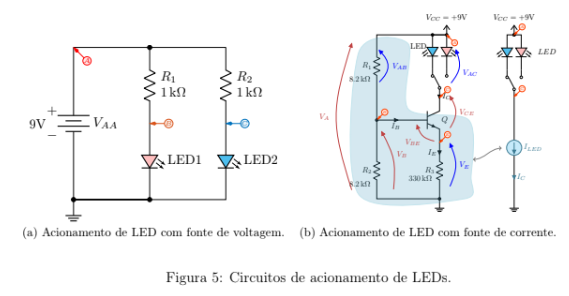

(a) O LED1 é um LED de cor vermelha ou amarela comum.

(b) O LED2 é um LED de alto brilho de cor azul ou branca (equivale aproximada-

mente a dois LEDs comuns em série).

(c) O LED acionado com fonte de corrente constante (vide Figura 5(b)) deve ser

analisado considerando os dois casos:

    i. LED1 (vermelho ou amarelo).

    ii. LED2 (azul).

Dica: Para analisar o circuito teoricamente, considerar o transistor BC547 ou BC549

como sendo ideal, i.e. com |VBE| = 0.7V e IB ≈ 0. Tire foto da sua montagem que

permita identificá-lo. Cada aluno deve ilustrar a montagem de seu grupo no relatório.

Faça a sua montagem ser tecnicamente de alta qualidade!

____________________________________________________________________________

Resposta: Responder aqui com os valores medidos para os itens desta questão.

**Resposta:**

- **Circuito A**

**nó A = 8,95V**

**nó B = 1,99V**

**nó C = 2,77V**

**It = I1 + I2**

**I1 = Vab/R1**

**I1 = (8,95 - 1,99)/1000**

**I1 = 0,00696A**

**I2 = Vac/R2**

**I1 = (8,95 - 2,77)/1000**

**I1 = 0,00618A**

**It = 0,00696 + 0,00618**

**I****T****= 0,01314A**

**V****AB** **= 7,2V**

**V****AC**** = 6,4V**

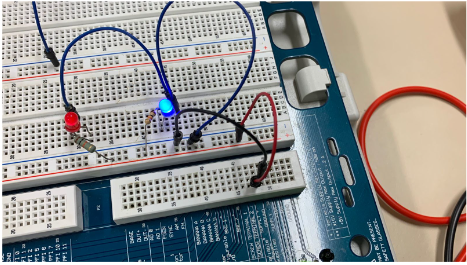

- **Circuito B**

- **Led azul**

**Nó A = 8,97V**

**Nó B = 4,3V**

**Nó C = 6,0V**

**Nó E = 3,6V**

**V****D**** = 0V**

**I****E**** = 0,01A = 11mA**

**I****B**** = 11mA****I****C**** = 0,01A = 11mA**

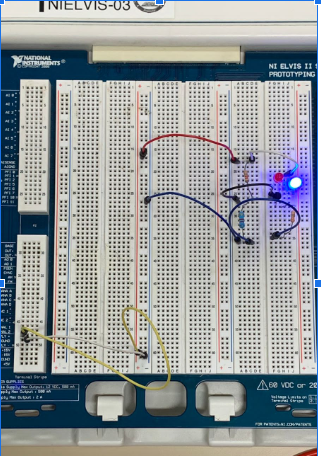

- **Led vermelho**

**Nó A = 8,9V**

**Nó B = 4,3V**

**Nó C = 7,11V**

**Nó E = 3,6V**

**V****D**** = 0V**

**I****E**** = 0,01A = 11mA**

**I****B**** = 11mA****I****C**** = 0,01A = 11mA**

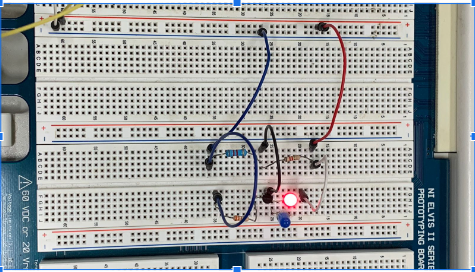

e este sou eu 

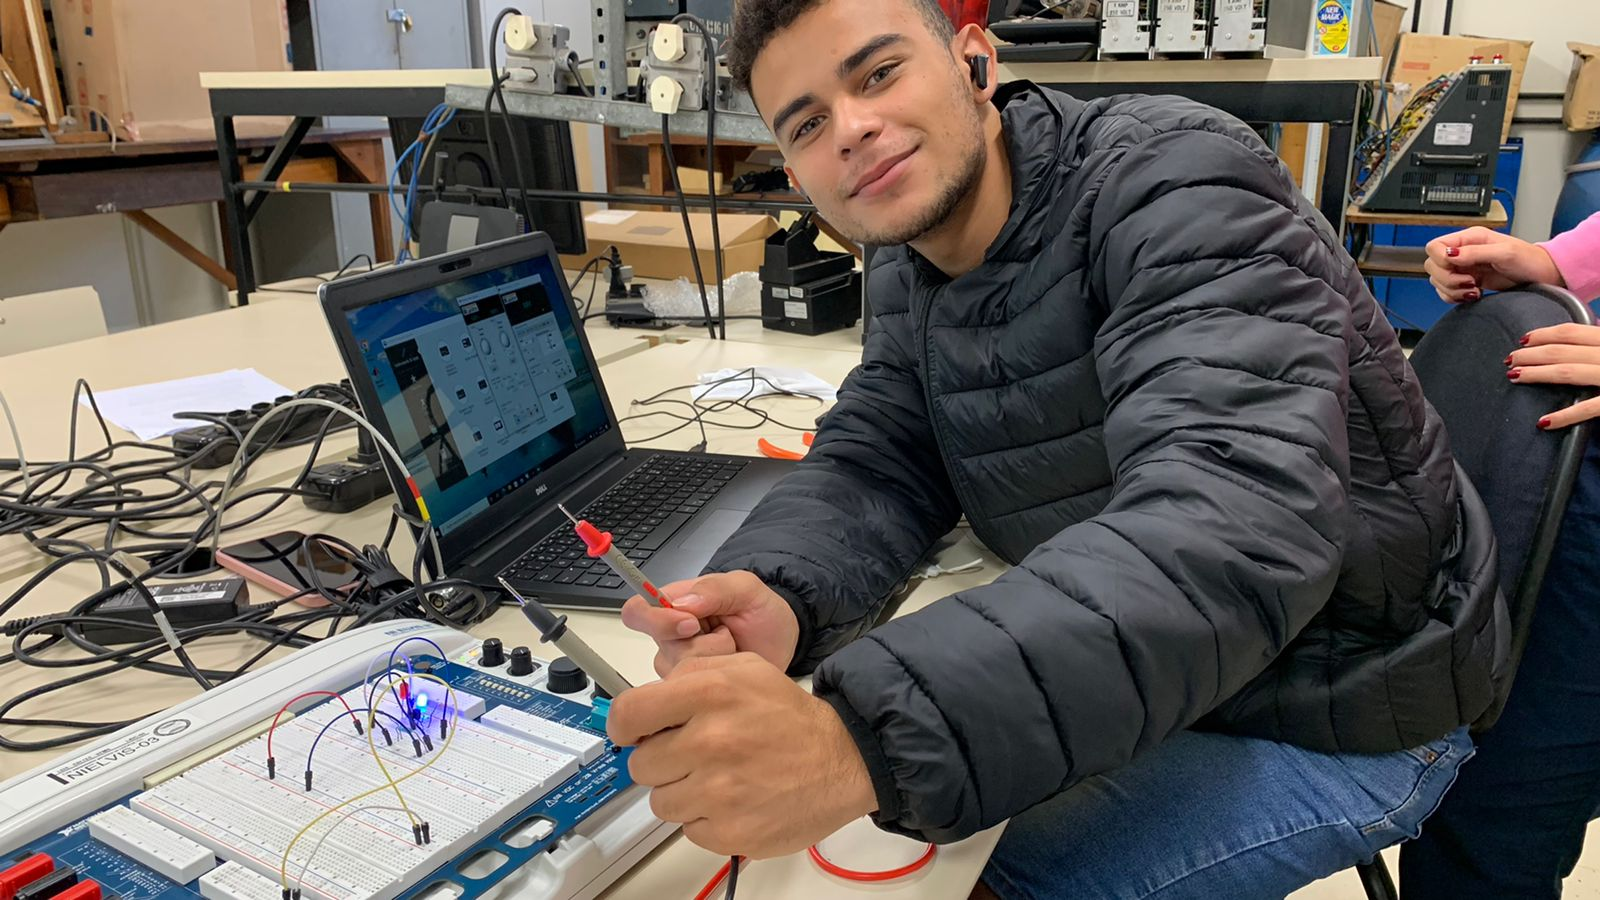

______________________________________________________________

## 2.2 Conclusões e sugestões

____________________________________________________________________________

Resposta: Edite suas conclusões dentro do ambiente Resposta!

conlcuimos que o circuito 3b funciona como uma fonte de corrente para os leds e por isso brilham em tons parecidos, enquanto o circuito 3a não, por isso possuem brilhos diferentes.

entendemos que um transistor npn possui um fonte de corrente controlada por corrente.

e entendemos que um led em serie com um resistor possui uma linha mais reta

____________________________________________________________________________